# Actividad #11

#### Fecha:

fecha = datetime('now', 'Format', 'dd-MM-yyyy');
disp(['Fecha actualizada: ', char(fecha)])

Fecha actualizada: 29-06-2024


#### Objetivos:

- Git: **Discard All Changes in Repository**

- Crear funciones : fLoadAllCSV.m

- Ejericios con boxchart y histogram 

#### Nombre:

- sunombre

#### Repository:

- [https://github.com/vasanza/SSE](https://github.com/vasanza/SSE)

#### Librarys:

- [https://github.com/vasanza/Matlab_Code](https://github.com/vasanza/Matlab_Code)

- [https://es.mathworks.com/help/matlab/ref/ls.htm](https://es.mathworks.com/help/matlab/ref/ls.htm)

- [https://es.mathworks.com/help/matlab/ref/matlab.git.gitrepository.discardchanges.html#d126e406558](https://es.mathworks.com/help/matlab/ref/matlab.git.gitrepository.discardchanges.html#d126e406558)

## Paso 0: Descartar cualquier cambio realizado en el repositorio clonado

%Version Online, Opcion 1:
% Source Control -> Discard all changes
% Source Control -> git pull

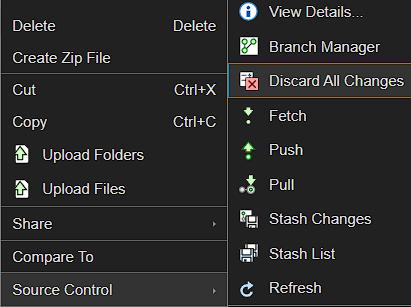

%Version Online, Opcion 2:
% repo = gitrepo;
% discardChanges(repo,repo.ModifiedFiles);
% Source Control -> git pull

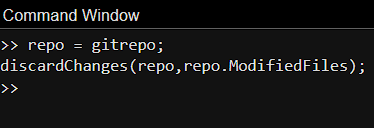

% Version para PC, en el Bash del Git:
% git status
% git reset --hard
% Git pull

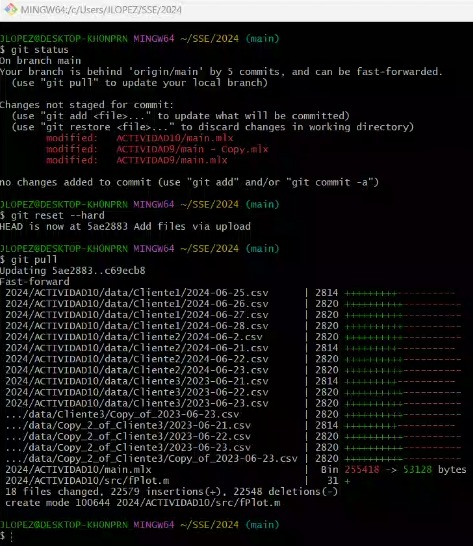

## Paso 1: Limpiar variables y linea de comandos

clear % Para borrar el workspace y liberar memoria RAM
clc  % Limpiar el command window
CurretFolder = cd;%Linux: Addres Current folder

## Paso 2.- Configuración de carpeta ./src para librerias

%nombre de la carpeta donde estan los codigos
addpath(genpath('./src'));

## **Paso 3- Configuranción de carpeta de ./data para datasets**

%Nombre de la carpeta donde estan los archvios csv
datapath=fullfile('./data/');

## **Paso 4- Buscar los nombres y **Cargar los datos **de todos los archivos dentro de la carpeta ./data**

% Funcion que retorna matriz 3D con los datos de todos los clientes
% pero se asume que hay una carpeta por cliente dengro de data.
SiEsPC= "true";
AllData = fLoadAllCSV(datapath,SiEsPC);

## Paso 5: Set de Nombres de variables and Max Values

Es importante que el archivo csv se encuentre en la misma carpeta que el main

%Estos son los nombres de las variables
vname=["Corriente","Voltaje","variable3","variable4","variable5"];
MaxColumnas=size(AllData,2);
MaxFilas=size(AllData,1);
MaxClient=size(AllData,3);

## Paso 6: Graficar el dataset

Seleccionar el numero de variables a mostrar


nvar=5;
nfilas=10;
Cliente=4;

## Paso 7: Personalizar las graficas con los EstilosLinea

LinK: [https://es.mathworks.com/help/matlab/ref/plot.html](https://es.mathworks.com/help/matlab/ref/plot.html)

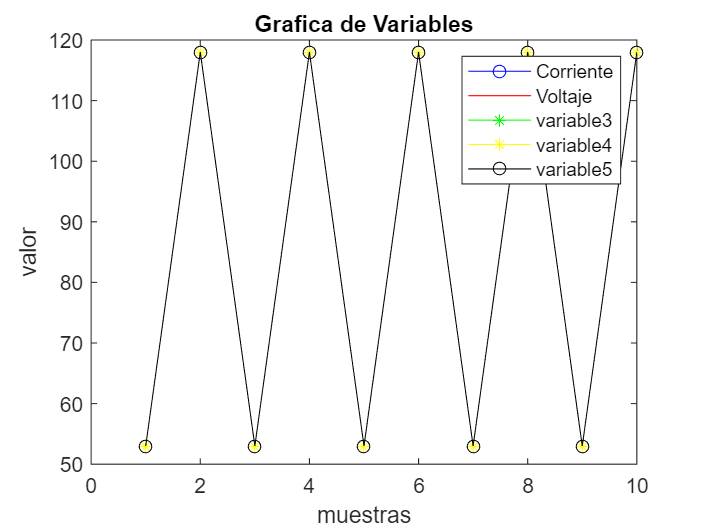

%Se limita la cantidad de filas y columnas a graficar x cliente
DatosPlot=AllData(1:nfilas,1:nvar,Cliente);
EstilosLinea=["-ob","-r","-*g","-*y","-ok"];

fPlot(DatosPlot,vname,EstilosLinea);

## Paso 8: Graficas para analizar los datos

LinK: [https://es.mathworks.com/help/matlab/ref/plot.html](https://es.mathworks.com/help/matlab/ref/plot.html)

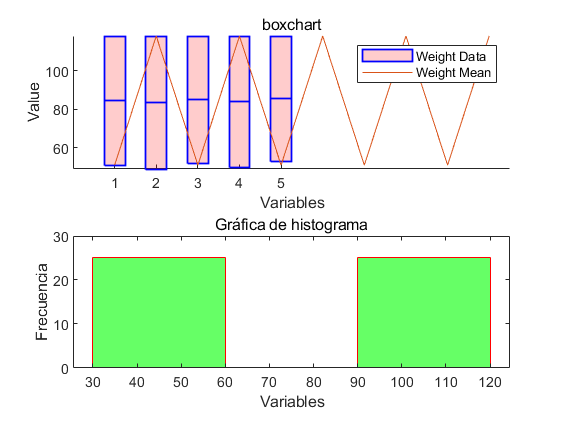

figure

subplot(2,1,1)
b=boxchart(DatosPlot);
hold on
plot(DatosPlot(:,1))
b.BoxFaceColor='r';b.BoxLineColor='b';
legend(["Weight Data","Weight Mean"])

subtitle("boxchart");
xlabel('Variables')
ylabel('Value')

subplot(2,1,2)
h=histogram(DatosPlot);
subtitle("Gráfica de histograma")
xlabel('Variables')
ylabel('Frecuencia')
h.EdgeColor='r';h.FaceColor='g';
hold off